# Assignment 1: Convolution

## G**eneral Instructions:**

- Make sure you use the exact function declarations given in the question descriptions. Changes of any kind will be penalized.

- Save every function in a separate .m file with the correct function name (e.g. functionName.m)

- Plots and discussion should be included in this Live Script (.mlx) file itself

- Plots should be properly and extensively labeled.

- Core MATLAB functions are allowed **UNLESS SPECIFIED OTHERWISE**. Functions from toolboxes (such as Signal Processing Toolbox) are **NOT ALLOWED** unless explicitly specified otherwise.

- Keep all your code in the `student` folder. Rename it to your GT username, zip it, and upload the zip file on Canvas.

- Clarification edits will be shown in **bold**.

- **STRONGLY RECOMMENDED: **Clear all variables and run this script in its entirety before submission. Make sure everything runs okay **in one go** from top to bottom.

**The purpose of this assignment is to guide you through the important concept of convolution.**

% % INITIALIZATION CODE. DO NOT CHANGE.
% 
% clearvars;
% 
% restoredefaultpath;
% 
% % Determine where your mlx-file's folder is.
% assignmentFolder = fileparts(fileparts(matlab.desktop.editor.getActiveFilename)); 
% % Add that folder plus all subfolders to the path.
% addpath(genpath(assignmentFolder));

% INITIALIZATION CODE. DO NOT CHANGE. 

 

clearvars; 

restoredefaultpath; 

 

% take care of path 

 

assignmentFolder = fileparts(matlab.desktop.editor.getActiveFilename);  

addpath(genpath(assignmentFolder)); 

 

topFolder = fileparts(fileparts(assignmentFolder));  

addpath(topFolder); 

addpath(genpath(fullfile(topFolder, "instructor", "qgrader"))); 

 

utilFolder = fullfile(fileparts(fileparts(topFolder)), "autograder");  

addpath(genpath(utilFolder)); 

 

assetFolder = fullfile(fileparts(fileparts(utilFolder)), "MUSI-6202-Assignments", "assignments", "assignment1", "assets"); 

addpath(genpath(assetFolder)); 

## Question 0: ** Setting up the MATLAB script [5]**

Create your copy of this MATLAB Live Script (.mlx) titled `assignment1.mlx`.

This script should call the functions below in the specified order, read the files, and generate all the required plots / figures (with proper axes and labels wherever required). This script will be executed for grading.  

Set the variable `studentId` to your GT username (e.g. `gburdell3, alerch3, kwatchar3`). **DO NOT USE YOUR EMAIL ALIAS.**

% CHANGE THIS
studentId = 'jli3269'; 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
score = 100; % SCORE OUT OF 100
autograde('q0', struct('score', score), studentId);

q0:	 5.00 / 5.00


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Question 1: **Time Domain Convolution: [30]**

**Do not use the built-in functions **`conv`** or **`conv2`** in your implementation. You may only use them to check your implementation.**

In this part, you will write a method to compute the sample by sample time domain convolution of 2 signals. The formula for discrete convolution is given by


$$(x \ast h)[k]=\sum_{i=\max(1,k+1-n)}^{\min(k,m)}x[i] h[k-i+1]$$


where $m$ is the length of $x$ and $n$ is the length of $h$.

### Q1(a) [15]

Write a MATLAB function 

`y = myTimeConv(x,h)` 

that computes the sample by sample time domain convolution of two signals. `x` and `h` are the signal and impulse response respectively and must be column vectors. `y` is the convolution output and also must be a column vector (single channel signals only). 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q1a', [], studentId);

q1a:	 15.00 / 15.00
Trial #1 output
  - Correct shape.
  - Correct values.
Trial #2 output
  - Correct shape.
  - Correct values.
Trial #3 output
  - Correct shape.
  - Correct values.
Trial #4 output
  - Correct shape.
  - Correct values.
Trial #5 output
  - Correct shape.
  - Correct values.
Trial #6 output
  - Correct shape.
  - Correct values.
Trial #7 output
  - Correct shape.
  - Correct values.
Trial #8 output
  - Correct shape.
  - Correct values.
Trial #9 output
  - Correct shape.
  - Correct values.
Trial #10 output
  - Correct shape.
  - Correct values.
Trial #11 output
  - Correct shape.
  - Correct values.
Trial #12 output
  - Correct shape.
  - Correct values.
Trial #13 output
  - Correct shape.
  - Correct values.
Trial #14 output
  - Correct shape.
  - Correct values.
Trial #15 output
  - Correct shape.
  - Correct values.
Trial #16 output
  - Correct shape.
  - Correct values.
Trial #17 output
  - Correct shape.
  - Correct values.
Trial #18 output
  - Correct shape.
 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Q1(b) [5]

If the length of `x` is 200 and the length of `h` is 100, what is the length of `y` ? Create a variable named `convLength` to store your answer.

lx = 200; lh = 100;
convLength = abs(lx + lh) - 1;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q1b', struct('ans', convLength), studentId);

q1b:	 5.00 / 5.00


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Q1(c) [10]

In your main script define `x` as a DC signal of length 200 (constant amplitude of 1) and `h` as a symmetric triangular signal of length 51 (0 at the first and last sample and 1 in the middle). 

Add a function call to `myTimeConv()` in your script to compute `y_time` as the time-domain convolution of `x` and `h` as defined above. Plot the result, labelling the axes appropriately.

**Useful methods:** `linspace()`

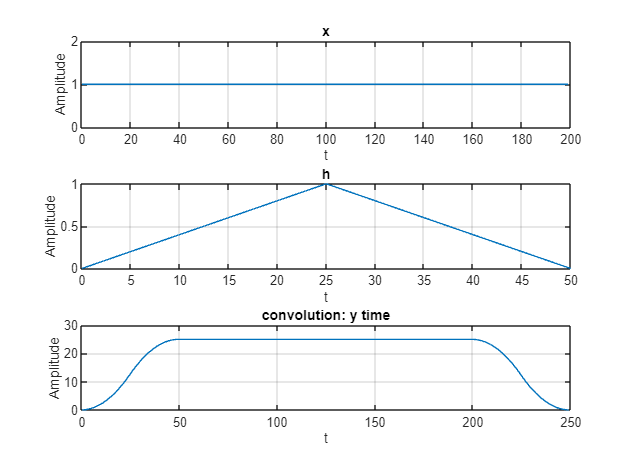

% ADD YOUR CODE

x = ones(200, 1); % Change this
h = [linspace(0, 1, 26) linspace(1-1/25, 0, 25)]'; % Change this
y_time = myTimeConv(x, h); % Change this

figure('Name', 'Q1(c): y_time plot'); % plot figures
subplot(3,1,1), plot(0:length(x)-1, x);
title('x');xlabel('t');ylabel('Amplitude');grid on;
subplot(3,1,2), plot(0:length(h)-1, h);
title('h');xlabel('t');ylabel('Amplitude');grid on;
subplot(3,1,3), plot(0:length(y_time)-1, y_time);
title('convolution: y time');xlabel('t');ylabel('Amplitude');grid on;

% END OF YOUR CODE

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
plotScore = 95; % SCORE OUT OF 100
autograde('q1c', struct('x', x, 'h', h, 'y_time', y_time, ...
    'plotScore', plotScore, 'comment', 'should use "sample" instead of "t" in xlabel, or should define what t represents'), studentId);

q1c:	 9.88 / 10.00
x
  - Correct shape.
  - Correct values.
h
  - Correct shape.
  - Correct values.
y_time
  - Correct shape.
  - Correct values.


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## **Question 2: Frequency Domain Convolution: [30]**

**Again, do not use the built-in functions **`conv`** or **`conv2`** in your implementation. You may only use them to check your implementation.**

In this part, you will write a method which computes the convolution of two signals in the frequency domain. First, compute the DFT of each of the entire signals, multiply them in frequency domain, and then compute the inverse DFT to get your result. 

**Useful functions:** `fft()` and `ifft()`

### Q2(a) [20]

Write a MATLAB function 

`y = myFreqConv(x,h)` 

that computes frequency domain convolution of two signals. 

Again, `x` and `h` are the signal and impulse response respectively and must be column vectors. `y` is the convolution output and also must be a column vector (single channel signals only).

**Note:** you may have to zeropad the signals appropriately before the transform - discuss in the forums what that means 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q2a', [], studentId);

q2a:	 20.00 / 20.00
Trial #1 output
  - Correct shape.
  - Correct values.
Trial #2 output
  - Correct shape.
  - Correct values.
Trial #3 output
  - Correct shape.
  - Correct values.
Trial #4 output
  - Correct shape.
  - Correct values.
Trial #5 output
  - Correct shape.
  - Correct values.
Trial #6 output
  - Correct shape.
  - Correct values.
Trial #7 output
  - Correct shape.
  - Correct values.
Trial #8 output
  - Correct shape.
  - Correct values.
Trial #9 output
  - Correct shape.
  - Correct values.
Trial #10 output
  - Correct shape.
  - Correct values.


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Q2(b) [10]

Keeping the definitions of `x` and `h` the same as in Question 1.c, add a function call to `myFreqConv()` in your main script to the compute `y_freq` as the frequency domain convolution of `x` and `h` as defined above in Question 1. Plot the result, labelling the axes appropriately.

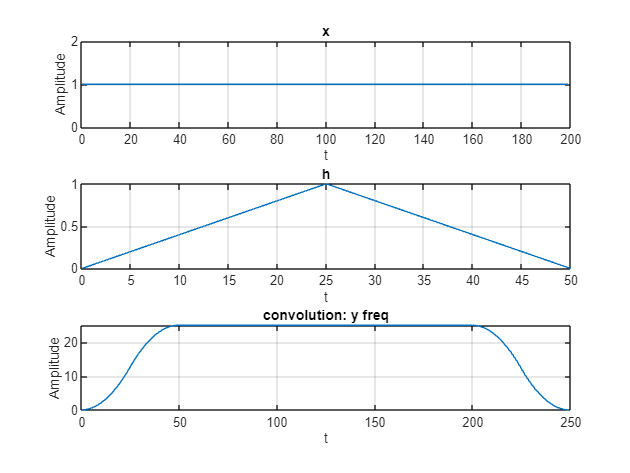

% ADD YOUR CODE
x = ones(200, 1); % Change this
h = [linspace(0, 1, 26) linspace(1-1/25, 0, 25)]'; % Change this
y_freq = myFreqConv(x, h); % Change this

figure('Name', 'Q2(b): y_time plot'); % plot figures
subplot(3,1,1), plot(0:length(x)-1, x);
title('x');xlabel('t');ylabel('Amplitude');grid on;
subplot(3,1,2), plot(0:length(h)-1, h);
title('h');xlabel('t');ylabel('Amplitude');grid on;
subplot(3,1,3), plot(0:length(y_freq)-1, y_freq);
title('convolution: y freq');xlabel('t');ylabel('Amplitude');grid on;


% END OF YOUR CODE

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
plotScore = 95; % SCORE OUT OF 100
autograde('q2b', struct('y_freq', y_freq, ...
    'plotScore', plotScore, 'comment', 'should use "sample" instead of "t" in xlabel, or should define what t represents'), studentId);

q2b:	 9.88 / 10.00
y_freq
  - Correct shape.
  - Correct values.


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## **Question 3. Compare with MATLAB Implementation: [20]**

In this part, you will compare your implementation with the built-in MATLAB `conv()` method. 

### Q3(a) [20]

Write a function 

`[m, mabs, stdev, time] = compareConv(x, h)` 

that compares the output of the convolution from both `myTimeConv()` and `myFreqConv()` with the built-in matlab `conv()` function. 

Again, `x` and `h` are the signal and impulse response respectively and must be column vectors. The function should compute the convolution result of `myTimeConv()` and `myFreqConv()` and compare it with that of `conv()`. It must return the following parameters:

- `m`: 2x1 vector of the mean difference of the outputs of both methods compared to conv()

- `mabs`: 2x1 vector of the mean absolute difference of the outputs of both methods compared to conv()

- `stdev`: 2x1 standard deviation of the difference of the outputs of both methods compared to conv() 

- `time`: 3x1 vector containing the running time of each method. Useful methods for measuring time: tic, toc.

For all output variables, the first element should be for the time-domain method, and the second for the frequency-domain method. The last element in the `time` variable should be for the built-in `conv()` method.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q3a', [], studentId);

q3a:	 20.00 / 20.00
m
  - Correct shape.
  - Correct values.
mabs
  - Correct shape.
  - Correct values.
stdev
  - Correct shape.
  - Correct values.
time
  - Correct shape.
  - Correct values.


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Q3(b) [5]

Using the attached files `piano.wav` and `impulse-response.wav` as `x` and `h` respectively, add a function call to `compareConv()` method in your main script and report the output.

% ADD YOUR CODE
x = audioread("assets/piano.wav");
h = audioread("assets/impulse-response.wav");

[mout, mabsout, stdevout, timeout] = compareConv(x, h); 
m = mout; % Change this
mabs = mabsout; % Change this
stdev = stdevout; % Change this
time = timeout; % Change this
% report the output
disp(m); % 2x1 vector of the mean difference of the outputs of both methods compared to conv()

     0
     0



disp(mabs); % 2x1 vector of the mean absolute difference of the outputs of both methods compared to conv()

     0
     0



disp(stdev); % 2x1 standard deviation of the difference of the outputs of both methods compared to conv()

     0
     0



disp(time); % 3x1 vector containing the running time of each method

    1.8705
    1.7702
    0.0047



% END OF YOUR CODE

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
reportScore = 100; % SCORE OUT OF 100
autograde('q3b', struct('m', m, 'mabs', mabs, 'stdev', stdev, ...
    'time', time, 'reportScore', reportScore), studentId);

q3b:	 5.00 / 5.00
m
  - Correct shape.
  - Correct values.
mabs
  - Correct shape.
  - Correct values.
stdev
  - Correct shape.
  - Correct values.
time
  - Correct shape.
  - Correct values.


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Q3(c) [10]

Which is the most time-efficient method and which is the least time-efficient method? Discuss the possible reasons.

**Answer:** The system built-in function conv() is the most time-efficient method, and myTimeConv() is the least time-efficient method. 

Among the three functions, the time complexity of myTimeConv() is O(N^2), and the FFT algorithm has an O(NlogN) time complexity, so the latter one is faster. As for the system built-in function conv(), it is written based on conv2(), and I cannot check the source code of conv2(), so it's difficult to know the time complexity. I guess the built-in function used the Toeplitz structure to optimize the multiplication, so it may be faster. Also, my function is interpreted MATLAB code with nested loops, so it may be slower than the built-in native function.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
discussScore = 100; % SCORE OUT OF 100
autograde('q3c', struct('score', discussScore), studentId);

q3c:	 10.00 / 10.00


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

autograde('summary', [], studentId);

Question    Score    Comment
--------    -----    -------
q0          5.00    
q1a         15.00    
q1b         5.00    
q1c         9.88    should use "sample" instead of "t" in xlabel, or should define what t represents
q2a         20.00    
q2b         9.88    should use "sample" instead of "t" in xlabel, or should define what t represents
q3a         20.00    
q3b         5.00    
q3c         10.00    
--------    -----    -------
Total       99.75    



load handel;
sound(y);